# LEDS Exam: September 11, 2023

# Project assignment

## Exercise 1: Estimation

clear all
close all
addpath ./Functions;

### **1. Understand the model structure**:

Student = 'Daniele Simonazzi';
Matriculation = '0001058929';

n = 20; % max model order
p = 2*n; % max model complexity

Let's plot the input and the output:

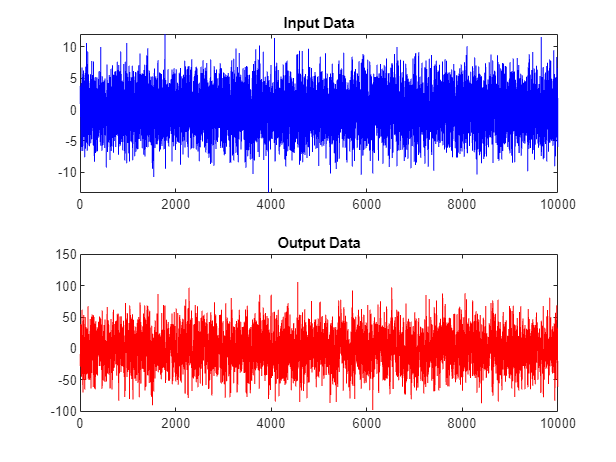

[example_measurements] = IdentifyThis(10000, Student, Matriculation);

example_u=example_measurements.u;
example_y=example_measurements.y;

figure;
hold on;

subplot(2,1,1);
plot(example_u,'b',LineWidth=.2);
title('Input Data');

subplot(2,1,2);
plot(example_y, 'r',LineWidth=.2);
title('Output Data')

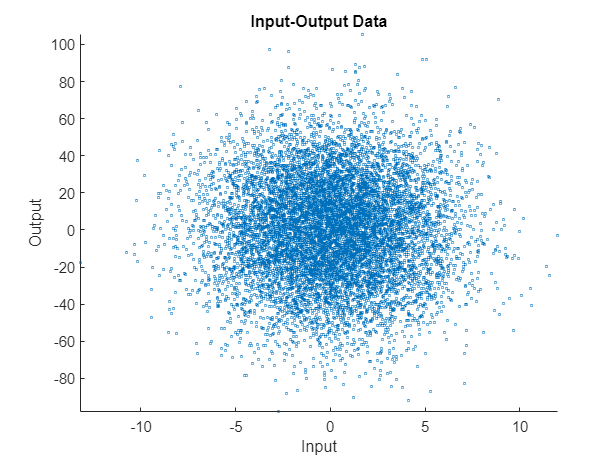

figure;
scatter(example_u, example_y, 2);
title('Input-Output Data')
xlabel('Input');
ylabel('Output');
axis tight;

It's clearly an ARX because of the presence of the inputs.

Let's recall the general expression of an ARX model of order $n$ and complexity$p = 2n$ where we assume$n_a = n_b=n$:

    
$$y(t) = -a_1y(t-1)-a_2y(t-2)-...-a_ny(t-n)+b_1u(t-1)+b_2u(t-2)+...+b_nu(t-n)+w(t)$$



$$A(z^{-1})y(t)=B(z^{-1})u(t) + w(t)$$


### **2. Define the required estimation algorithm:**

In this section it's defined the estimation algorithm used to identify the parameters ($\theta$) that represent the system.

Since the model is linear in the parameters it can always be written in the linear regression form:


$$y(t) = \varphi(t)^T\theta + \epsilon(t)$$


where:


$$\varphi(t) = [-y(t-1)\ \dots \ -y(t-n)\quad u(t-1)\ \dots \ u(t-n)]^T$$
 

and:


$$\theta= [a_1 \ \dots \ a_n\quad b_1 \ \dots \ b_n]^T$$


We can also write it in the vector form:


$$Y = H\theta + \epsilon$$


where $H$ is the Hankel matrix:


$$H =\left[\begin{array}{cccc}
-y(0) & -y(-1) & \cdots & -y(1-n) & u(0) & u(-1) & \cdots & u(1-n) \\
-y(1) & -y(0) & \cdots & -y(2-n) & u(1) & u(0) & \cdots & u(2-n) \\
\vdots & \vdots & \cdots & \vdots& \vdots & \vdots & \cdots & \vdots \\
-y(N-1) & -y(N-2)  & \cdots& -y(N-n) & u(N-1) & u(N-2) & \cdots & u(N-n)
\end{array}\right] = \left[\begin{array}{c}
-Hy & | & Hu\end{array}\right]
\]$$


In order to implent it the function [hank_mat](matlab:open('./Functions\hank_mat.m')) has been created.

The algorithm that has been chosen to solve this problem is the Least Square Method. It consists in finding the vector of parameters ($\theta$) which minimizes the following loss function:


$$J(\theta) = \frac{1}{N}\sum_{t=1}^N\epsilon^2(t) =  \frac{1}{N} \sum_{t=1}^N (y(t)-\varphi(t)^T\theta)^2= \frac{1}{N}(Y-H\theta)^T(Y-H\theta)$$


Where $\epsilon(t)$ is the residual at time $t$ or better the misfit between$y(t)
$ and its prediction$\hat{y(t)}
$:


$$\epsilon(t) = y(t) - \hat{y(t)} = y(t) - \varphi(t)^T\hat{\theta}
$$


The implementation of the loss function can be seen in the [ls_loss_function](matlab:open('./Functions\ls_loss_function.m')) (least square loss function) where instead of $N$ we have $N-n$ because the first $n$ samples are needed to compute the first $y(t)$. This correction will also apply to the next applications. The residuals vector is calculated separately([residual](matlab:open('./Functions\residual.m'))).

Finally in order to compute the LS estimation the [ls_arx](matlab:open('./Functions\ls_arx.m')) is used where it's performed:


$$\hat{\theta}_N = \bigg(\frac{H^TH}{N}\bigg)^{-1}\frac{H^TY}{N}$$


Let's now apply the algorithm considering $n$ models of different increasing order up to $n = 20$:

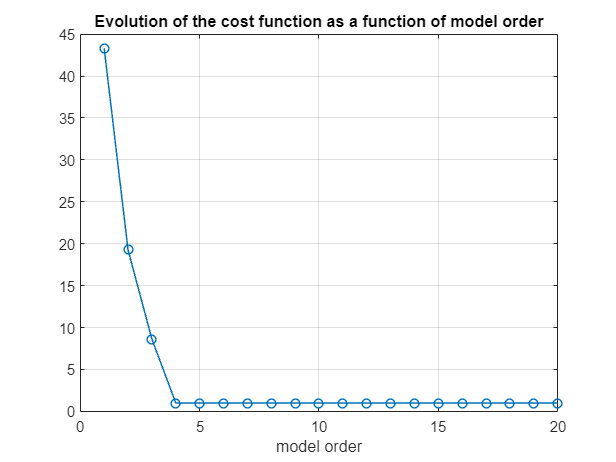

% create the structures that store the different results
theta_list = cell(1,n);
hankel_list = cell(1,n);
eps_list = cell(1,n);
J_theta_list = zeros(1,n);

for i = 1:n

    N=10000+i;

    [Measurements] = IdentifyThis(N, Student, Matriculation);
    u=Measurements.u;
    y=Measurements.y;
    
    Hu_temp = hank_mat(u,i); 
    Hy_temp= hank_mat(y,i);

    hankel_list{i} = horzcat(-Hy_temp,Hu_temp); % H = [ - Hy | Hu]

    theta_list{i} = ls_arx(y,hankel_list{i},N,i); % save the estimates of the theta for each order
    
    eps_list{i} = residual(y, theta_list{i}, hankel_list{i}, i); % save the residual vector

    J_theta_list(i) = ls_loss_function(eps_list{i},N,n);
end

figure;
plot(1:n,J_theta_list, "-o", "LineWidth", 1)
title("Evolution of the cost function as a function of model order")
xlabel("model order")
grid on

### **3. Estimate the model order:**

In this section the focus is on estimating the model complexity $p
$ or better choosing the 'best' model class $M_p(\theta)$. While doing so we need to avoid both overfitting and underfitting and we need to bear in mind the parsimony principle, ergo selecting the model with the smallest complexity among all the competing models.

Since the minimization of the loss function cannot be used as a way to evaluate the model complexity (it violates both the guidelines just made), a different criterion has been selected. Let's recall the criteria with complexity terms which are obtained by penalizing in some way the decrease of $J(\hat\theta_{N})$ with increasing complexity $p$.

In particular among the **FPE**, **AIC** and **MDL**, the last one has been selected.

Let's recall both the general form of these criteria and the specific **MDL** form:


$$V(\hat\theta_{N}) = N\log{J(\hat\theta_{N}) + f(N,p)$$



$$MDL = N\log{J(\hat\theta_{N}) + 2p\log{N}$$


The main reason for this choice is that the **MDL**, in general, leads to model of lower complexity wrt to **AIC** and **FPE **thanks to its propriety of getting consistent estimates.

Let's evaluate the **MDL** ([mdl](matlab:open('./Functions\mdl.m'))) for each order and save the order in which the value has its minimum:

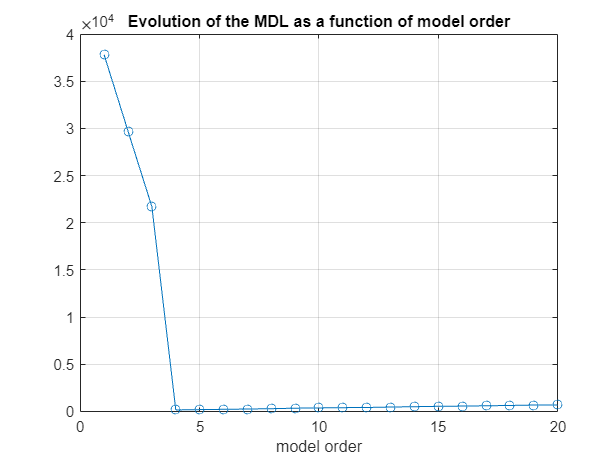

mdl_theta = zeros(n,1);

for i = 1:n

    mdl_theta(i) = mdl(J_theta_list(i),N,i);

end

figure;
plot(1:n, mdl_theta, '-o');
title("Evolution of the MDL as a function of model order")
xlabel("model order")
grid on

[minValue, n] = min(mdl_theta);
p = 2*n;

fprintf('Best model order n is: %4d\nBest model complexity p is: %4d', n, p);

Best model order n is:    4
Best model complexity p is:    8

N = 10000+n;
[Measurements] = IdentifyThis(N, Student, Matriculation);
u=Measurements.u;
y=Measurements.y;

theta_hat = theta_list{n};
hankel_hat = hankel_list{n};
eps_hat = eps_list{n};
J_theta_hat = J_theta_list(n);
fprintf('Estimated parameters:\na1 = %3f\ta2 = %3f\ta3 = %3f\ta4 = %3f\nb1 = %3f\tb2 = %3f\tb3 = %3f\tb4 = %3f',theta_hat)

Estimated parameters:
a1 = -0.001448	a2 = 0.000210	a3 = -0.002588	a4 = 0.001955
b1 = 5.539145	b2 = 5.027396	b3 = 3.986517	b4 = 2.084397

### **4. Validate the model:**

Once we estimated the model complexity and the vector of parameters $\hat{\theta}$ it's now asked to validate the model. The model assessment consists in evaluating the capability of the identified model to describe the process that has generated the data. 

First we assume that our data are well described by our linear regression model. By doing so we are able to make the following assumptions on the residual $\epsilon(t, \hat{\theta}_N)$:

- $\epsilon(t, \hat{\theta}_N)$ is a zero mean white process

- $\epsilon(t, \hat{\theta}_N)$ is uncorrelated with the input signal  $u(t)$

Let's now verify both these assumptions by performing first the Whiteness test on $\epsilon(t, \hat{\theta}_N)$ and then the Cross-Correlation test on $\epsilon(t, \hat{\theta}_N)$ and $u(t)$.

####  Whiteness Test

Considering a sequence of residuals $\epsilon(1,\hat\theta_N),\epsilon(2,\hat\theta_N),\dots,\epsilon(N,\hat\theta_N)$ a statistical test is performed:


$$\left\lbrace \begin{array}{ll}
H_0 :\epsilon \left(t,\hat{\theta_N } \right)\ \ is\ a\ zero\ mean\ white\ process \\
H_1 :\mathrm{not}\;H_0  
\end{array}\right.$$


 In particular a chi-square test has been chosen:


$$\left\lbrace \begin{array}{ll}
H_0: x \le \chi^2_{\alpha}(m)  \qquad accept H_0\\
H_1: x > \chi^2_{\alpha}(m) \qquad accept H_1 \end{array}$$


In order to do so the [whiteness_test](matlab:open('./Functions\whiteness_test.m')) function has been used. 

First we estimate the variance $\sigma^2_w$ with:


$$\hat{r}_\epsilon(0) = \frac{1}{N}\sum_{t=1}^{N}\epsilon(t)^2$$


and then the autocorrelation vector $\hat{r}_\epsilon$:


$$\hat{r}_\epsilon= [\hat{r}_\epsilon(1)\quad\hat{r}_\epsilon(2)  \ \dots \ \hat{r}_\epsilon(m)]^T$$


where:


$$\hat{r}_\epsilon(\tau) = \frac{1}{N}\sum_{t=1}^{N-\tau}\epsilon(t+\tau)\epsilon(t)$$


Then, under $H_0$:

- $\hat{r}_\epsilon(0) \to \sigma^2_w$ for$N \to \infty$

- $\hat{r}_\epsilon(\tau) \to 0\ \forall\tau \neq0$ for $N \to \infty$

we can define a chi-distributed quantity $x$:


$$x = N\frac{\hat{r}^T_{\epsilon}\hat{r}_{\epsilon}}{\hat{r}^2_{\epsilon}(0)}$$


compute the value of $\chi_{\alpha}^2(m)$ and compare its value with $x$.

Let's define the signifcance level $\alpha
$ and $m$ and run the test:

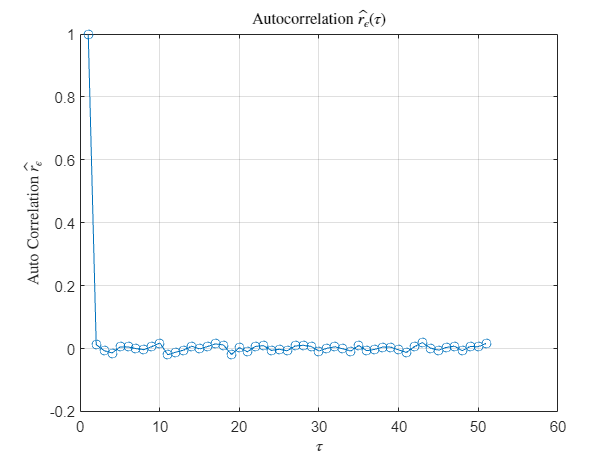

Whiteness test: PASSED	 41.294654 <= 67.504807

alpha = 0.05;
m = 50;

white_test = whiteness_test(eps_hat,N,n,m,alpha);

As the test confirm, the plot of the autocorrelation shows many similarity with the autocorrelation of a zero-mean white  process.

#### Cross-correlation Test

A similar reasoning can be made to test the cross correlation of $\epsilon(t, \hat{\theta}_N)$ and $u(t)$. In particular in this case:


$$\left\lbrace \begin{array}{ll}
H_0 :\epsilon \left(t,\hat{\theta_N } \right)\ and\ u(t)\ are\ uncorrelated \\
H_1 :\mathrm{not}\;H_0  
\end{array}\right.$$


In order to do so the [cross_correlation_test](matlab:open('./Functions\cross_correlation_test.m')) function has been used. 

First we estimate the variance $\sigma^2_w$ just like before and then the cross correlation vector $\hat{r}_{{\epsilon}u}$:


$$\hat{r}_{{\epsilon}u}= [\hat{r}_{{\epsilon}u}(\bar{\tau}+1)\quad\hat{r}_{{\epsilon}u}((\bar{\tau}+2)  \ \dots \ \hat{r}_{{\epsilon}u}(\bar{\tau}+m)]^T$$


where:


$$\hat{r}_{{\epsilon}u}(\tau) = \frac{1}{N}\sum_{t=1}^{N-\tau}\epsilon(t+\tau)u(t)$$


Let's notice that $\bar{\tau}$ has been selected such that it's greater than the model order $n$. This is due to the fact that, in the case of the LS method, the first $n$ terms of the cross correlation are zero by construction.

The Hankel matrix of the input has to be computed in order to estimate the sample autocorrelation/covariance matrix $\hat{\Sigma}_u(m)$ which is an estimate of:


$$E[\varphi_u(t,m)\ \varphi_u^T(t,m)] = \hat{\Sigma}_u(m) = \frac{1}{N}\sum_{t=1}^{N}\varphi_u(t,m)\ \varphi_u^T(t,m)$$


we then can define a chi-distributed quantity $x$:


$$x = N\frac{\hat{r}_{{\epsilon}u}^T\hat{\Sigma}_u^{-1}\hat{r}_{{\epsilon}u}}{\hat{r}^2_{\epsilon}(0)}$$


compute the value of $\chi_{\alpha}^2(m)$ and compare its value with $x$.

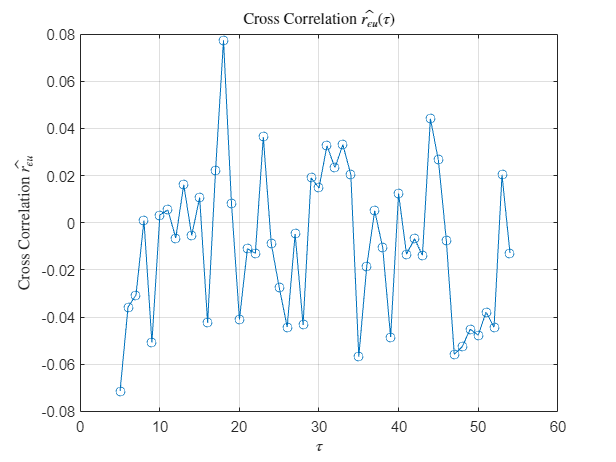

Cross Correlation test: PASSED	 54.974372 <= 67.504807

cross_corr_test = cross_correlation_test(eps_hat,u,N,n,m, alpha);

## Exercise 2: Classification

clear all
close all
addpath ./Functions;

### 1.**Understand the feature set in space**:

N=10000;

Student = 'Daniele Simonazzi';
Matriculation = '0001058929';

[FeatureSet] = ClassifyThose(N,Student,Matriculation);

Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Ntrain = length(Utrain);

Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;
Ntest = length(Utest);

Let's first change the labels in such a way that:


$$y(t) = \left\lbrace \begin{array}{ll}
1\ if\ u(t) \in C_1\\
0\ if\ u(t) \in C_2
\end{array}\right.$$


Ytrain= Ytrain-1;
Ytest= Ytest-1;

And let's plot the feature set in the input space:

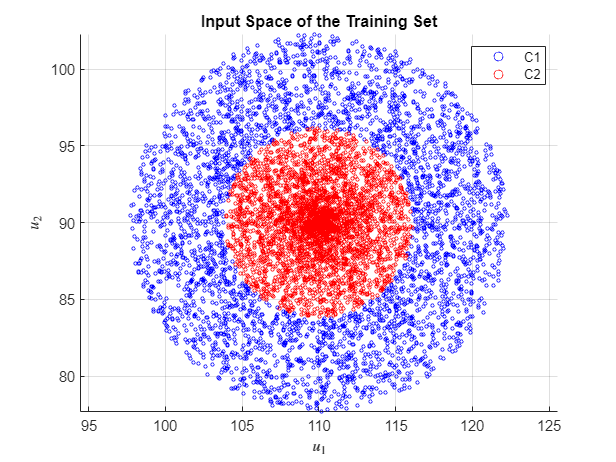

figure;
hold on;
grid on;
scatter(Utrain(Ytrain(:) == 1,1),Utrain(Ytrain(:) == 1,2),5, 'b')
scatter(Utrain(Ytrain(:) == 0,1),Utrain(Ytrain(:) == 0,2),5, 'r')
xlim([min(Utrain(:,1)), max(Utrain(:,1))]);
ylim([min(Utrain(:,2)), max(Utrain(:,2))]);
title('Input Space of the Training Set');
xlabel('$u_1$', 'Interpreter', 'latex');
ylabel('$u_2$', 'Interpreter', 'latex');
legend({'C1','C2'});
axis equal;

The data set is divided in 2 classes and the boundary between them is clearly non linear. We need to map our input space in a new space where the non linear boundary becomes a linear one.

Let's start by normalising the dataset ([normalize_data](matlab:open('./Functions\normalize_data.m'))) in order to avoid numerical problems in subsequent operations. This operation is performed by first finding the geometric barycentre of the dataset and then the greatest distance from it. Finally each input is divided by this value, resulting in a dataset where the 'circularity' is preserved.

After the normalization we proceed to the following linearization ([linearize_data](matlab:open('./Functions\linearize_data.m'))):


$$u(t)=\left[\begin{array}{ll}
u_1(t)\\
u_2(t)


\end{array} \right]$$

$$\to$$

$$\overline{u}(t)=\left[\begin{array}{ll}
(u_1(t) -mean(u_1))^2\\
(u_2(t) -mean(u_2))^2


\end{array} \right]$$


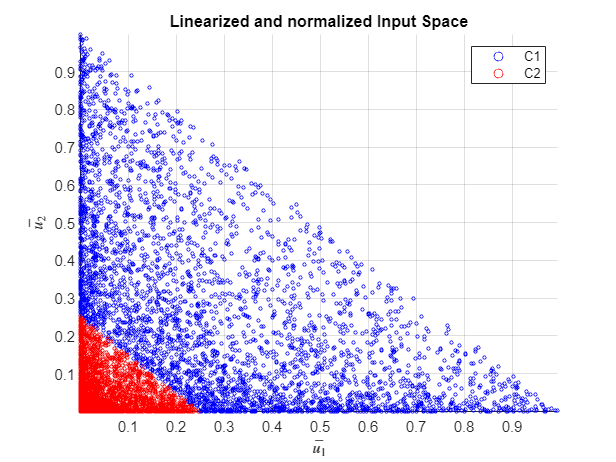

Utrain_norm = normalize_data(Utrain, Ntrain);
Utrain_linear =linearize_data(Utrain_norm);

figure;
hold on;
grid on;
scatter(Utrain_linear(Ytrain(:) == 1,1),Utrain_linear(Ytrain(:) == 1,2), 5,'b');
scatter(Utrain_linear(Ytrain(:) == 0,1),Utrain_linear(Ytrain(:) == 0,2),5, 'r');
xlim([min(Utrain_linear(:,1)), max(Utrain_linear(:,1))]);
ylim([min(Utrain_linear(:,2)), max(Utrain_linear(:,2))]);
title('Linearized and normalized Input Space');
xlabel('$\bar{u_1}$', 'Interpreter', 'latex');
ylabel('$\bar{u_2}$', 'Interpreter', 'latex');
legend({'C1','C2'});

### 2. **Define the required classification algorithm:**

Once the data set has been linearized, we can proceed by computing the linear decision boundary. This boundary is an hyperplane in $R^2
$ described by the equation:

    $\beta_0 + \beta_1\overline{u}_1(t)+\beta_2\overline{u}_2(t) = 0$ where $\overline{u}_i = u^2_i(t)$

that can be written in form:

  
$$\overline{\varphi}(t)^T\theta = 0$$


with:

$\overline{\varphi}(t) = [1\  \overline{u}_1(t)\  \overline{u}_2(t)]^T$ and $\theta = [\beta_0\ \beta_1\ \beta_2]^T$

In order to model the $P(C_1|u(t))$ and $P(C_2|u(t))$ we need to define a function $f(z(t))$, where $z(t) = \overline{\varphi}(t)^T\theta$such that:

- 
$$f(z(t))\ takes\ values\ in\ (0,1)$$


- 
$$f(0)=0.5$$


- 
$$f(z(t)) > 0.5\ (f(z(t)) < 0.5) \ when\ z(t) > 0\ ( z(t)< 0)$$


- $f(z(t)) \to 1$ when $z(t) \to \infty$

- $f(z(t)) \to 0$ when $z(t) \to -\infty$

This function is the logistic sigmoid ([sigmoid](matlab:open('./Functions\sigmoid.m'))):


$$f(z(t)) = \frac{e^{z(t)}}{1+e^{z(t)}} =  \frac{1}{1+e^{-z(t)}}$$


which will define the conditional probabilities:


$$P(C_1|u(t)) = f(z(t))$$



$$P(C_2|u(t)) = 1-f(z(t))$$


The focus is now on finding the estimate $\hat{\theta}$ that maximizes the poster probability of the observation:

 
$$Y = [y(1)\ \dots \ y(N)]^T$$


In order to do so we use the maximum likelihood estimation which leads us to the minimization problem:


$$\min_{\theta} J(\theta)$$


with the following loss function ([lr_loss_function](matlab:open('./Functions\lr_loss_function.m'))):


$$J(\theta) = -log(P(Y|\theta)) = - \sum_{t=1}^N [y(t)log(f(z(t))) + (1-y(t))log(1-f(z(t)))]$$


We can solve this problem in many ways, in this case the Newton-Raphson algorithm has been selected.

Let's recall that it's an iterative algorithm where at each step the estimation is updated in this way:


$$\hat{\theta}^{k+1} = \hat{\theta}^k - \eta_kJ^{''}(\hat{\theta}^k)^{-1}J^{'}(\hat{\theta}^k)^T$$


where:

- $\eta_k$ is the stepsize.

- 
$$J^{'}(\theta) = \sum_{t=1}^N[f(z(t))-y(t)]\varphi(t)=\Phi^T(F(\theta) - Y)$$


- 
$$J^{''}(\theta)= \sum_{t=1}^Nf(z(t))(1-f(z(t)))\varphi(t)\varphi^T(t)=\Phi^TW(\theta)\Phi$$


and:

- 
$$\Phi = \left[\begin{array}{ll}
1 & u_1(1) & \dots & u_r(1) \\
\vdots & u_1(2)  & \dots & u_r(2) \\
\vdots & \vdots & \ddots & \vdots \\
1 & u_1(N) & \dots & u_r(N)


\end{array} \right]$$


- 
$$F(\theta) = [f(z(1))\ \dots \ f(z(N))]^T$$


- 
$$W(\theta) =diag[f(z(1))(1-f(z(1)), ....,f(z(N))(1-f(z(N))]$$


The algorithm ([newton_raphson](matlab:open('./Functions\newton_raphson.m'))) is now:


$$\hat{\theta}^{k+1} = \hat{\theta}^k - \eta_k(\Phi^TW(\theta)\Phi)^{-1}\Phi^T(F(\theta) - Y))$$


Since the algorithm is iterative we need both an initial condition for $\hat{\theta}$ and a stopping criterion:

For the former I chose a vector:

 
$$\hat{\theta}^0 = [0.1\  0.1\  0.1]$$


while for the latter I decided to check either the modulus of the difference between two consecutive cost functions or the number of iterations:


$$|J(\hat{\theta}^{k+1}) - J(\hat{\theta}^k)| \leq \epsilon \qquad |\qquad k \ge Max\ Iterations$$


Since the algorithm may be unstable, in particular due to the fact that the Hessian $J^{''}(\theta)$ may be ill-conditioned, i decided to add a penalty term to the loss function (Regularization):


$$J(\theta) =  J_{NR}(\theta) + \lambda\beta^T\beta$$


with:


$$\beta=\left[\begin{array}{ll}
\beta_1\\
\beta_2


\end{array} \right]$$


and $\lambda > 0$ being a tuning parameter.

By doing so a term $\lambda I_p$ is added to the Hessian, guaranteeing a better conditioned matrix.

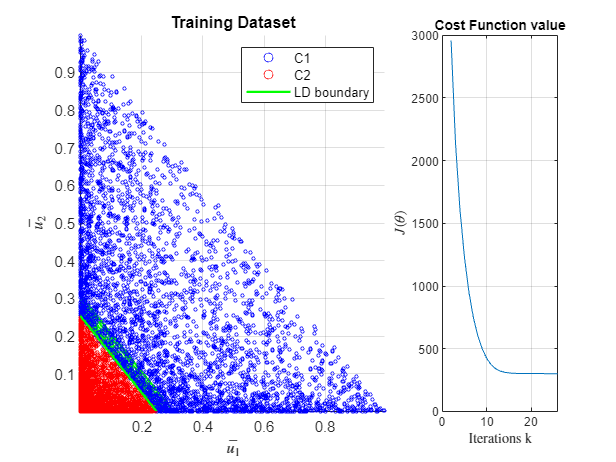

animate = true; 

stepsize = 0.5;
lambda = 0.1;

k = 1;
max_iterations = 1000;
epsilon = 10^(-3); % threshold for the stopping criterion
theta = [0.1;0.1;0.1]; % initialize the theta
PHI_train = horzcat(ones(Ntrain,1), Utrain_linear); % construct the matrix PHI (Nx3)
J_theta = lr_loss_function(Ytrain, PHI_train, theta, lambda); % compute the first loss function

while 1

    descent = newton_raphson(Ytrain, PHI_train, theta, lambda); % compute the descent
    theta = theta - stepsize*descent; % update the estimation of theta
    J_theta(k+1) = lr_loss_function(Ytrain, PHI_train, theta, lambda); % compute the new loss function

    % stopping criterion
    if (abs(J_theta(k+1)-J_theta(k)) < epsilon) || (k >= max_iterations)
        break;
    end
    
    % plot
    if animate
        
        subplot(1,3,[1, 2]);
        hold on;
        grid on;
        scatter(Utrain_linear(Ytrain(:) == 1,1),Utrain_linear(Ytrain(:) == 1,2),5,'b')
        scatter(Utrain_linear(Ytrain(:) == 0,1),Utrain_linear(Ytrain(:) == 0,2),5,'r')
        xlim([min(Utrain_linear(:,1)), max(Utrain_linear(:,1))]);
        ylim([min(Utrain_linear(:,2)), max(Utrain_linear(:,2))]);
        Xlim=xlim();
        xspace = Xlim(1):0.1:Xlim(end);
        LD_boundary = (theta(1) + xspace.*theta(2))./(-theta(3));
        plot(xspace,LD_boundary,'g','LineWidth',1.5)
        hold off
        title('Training Dataset');
        xlabel('$\bar{u_1}$', 'Interpreter', 'latex');
        ylabel('$\bar{u_2}$', 'Interpreter', 'latex');
        legend({'C1','C2','LD boundary'});
        
        subplot(1,3,3);
        plot(2:k,J_theta(2:k),'-');
        grid on;
        title('Cost Function value');
        xlabel('Iterations k', 'Interpreter', 'latex');
        ylabel('$J(\theta)$', 'Interpreter', 'latex');

        pause(0.1);
    end

    k = k+1;
end

It can be seen that in a few iterations the algorithm converges. And in particular it converges to a vector of parameters $\hat{\theta}$ whose norm is less then the one we would have obtained without regularization. It's worth to note, though, that increasing the value of $\lambda$ may lead to worse estimations of the linear decision boundary, ergo greater error rates, due to the added bias.

fprintf('Estimated parameters:\nbeta_0 = %3f\tbeta_1 = %3f\tbeta_2 = %3f',theta);

Estimated parameters:
beta_0 = -9.947161	beta_1 = 39.986677	beta_2 = 39.239516

Let's now plot the non linearized training set and the estimated non linear decision boundary obtained by reversing the previous transformation:

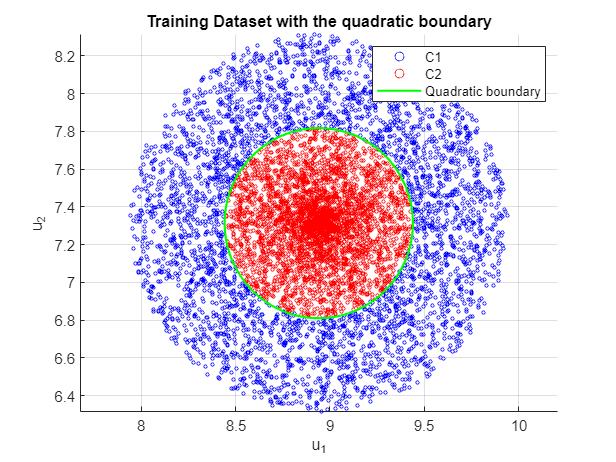

figure;
hold on;
grid on;
scatter(Utrain_norm(Ytrain(:) == 1,1),Utrain_norm(Ytrain(:) == 1,2),5,'b');
scatter(Utrain_norm(Ytrain(:) == 0,1),Utrain_norm(Ytrain(:) == 0,2),5,'r');

xlim([min(Utrain_norm(:,1)), max(Utrain_norm(:,1))]);
ylim([min(Utrain_norm(:,2)), max(Utrain_norm(:,2))]);
Quadratic_boundary = @(u1,u2) (theta(1)+theta(2)*(u1-mean(Utrain_norm(:,1))).^2+theta(3)*(u2-mean(Utrain_norm(:,2))).^2);
fimplicit(Quadratic_boundary, 'g', 'LineWidth', 1.5)
hold off;
title('Training Dataset with the quadratic boundary');
xlabel('u_1');
ylabel('u_2');
legend({'C1','C2','Quadratic boundary'});
axis equal;

### **3. Verify and test your classificator: **

Once estimated the $\hat{\theta}$ and its associated boundary $\hat{z(t)}$ we can finally evaluate the performance of our classifier by computing the error rate ([error_rate](matlab:open('./Functions\error_rate.m'))):


$$E_r = \frac{1}{N} \sum_{t=1}^{N}I(y(t),\hat{y}(t))$$


where$\hat{y}(t)$ is the prediction of ${y}(t)$ provided by the classifier and$I(y(t),\hat{y}(t))$ is an indicator variable:


$$I(y(t),\hat{y}(t)) = \begin{cases} 1 & if\ y(t) \neq \hat{y}(t) \\ 0 & if\ y(t) = \hat{y}(t) \end{cases}$$


The error rate is thus the fraction of misclassified observations.

In particular once obtained $\hat{z(t)}$, the$f(\hat{z(t)})$ is computed and the input is assigned to either class $C_1$ or $C_2$ as follows:


$$if\ f({\hat{z}(t)}) > 0.5 \to u(t) \in C_1$$
 


$$if\ f({\hat{z}(t)) < 0.5 \to u(t) \in C_2$$
 

Let's test our classifier:

e_newthon = error_rate(Ytrain, PHI_train, theta, Ntrain);
fprintf('Error rate: %f\t', e_newthon);

Error rate: 0.001857	

It is now time to test the classifier on the test set. In order to do it we have to classify new inputs and then evaluate the associated error rate.

We proceed with the same steps as before. Let's first visualize the new data set:

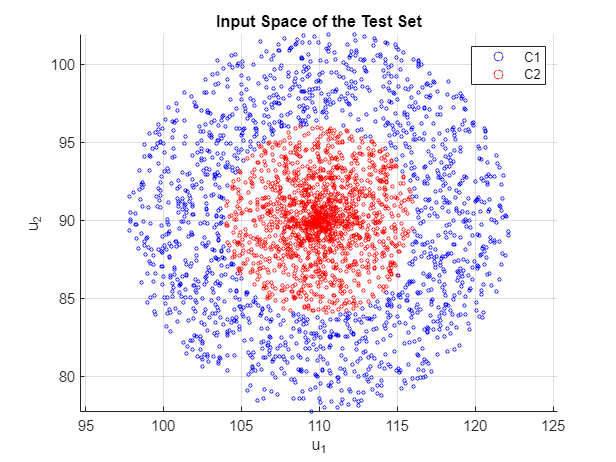

figure;
scatter(Utest(Ytest(:) == 1,1),Utest(Ytest(:) == 1,2),5, 'b')
hold on;
grid on;
scatter(Utest(Ytest(:) == 0,1),Utest(Ytest(:) == 0,2),5, 'r')
xlim([min(Utest(:,1)), max(Utest(:,1))]);
ylim([min(Utest(:,2)), max(Utest(:,2))]);
title('Input Space of the Test Set');
legend({'C1','C2'});
xlabel('u_1');
ylabel('u_2');
axis equal;

Let's then normalize and linearize it:

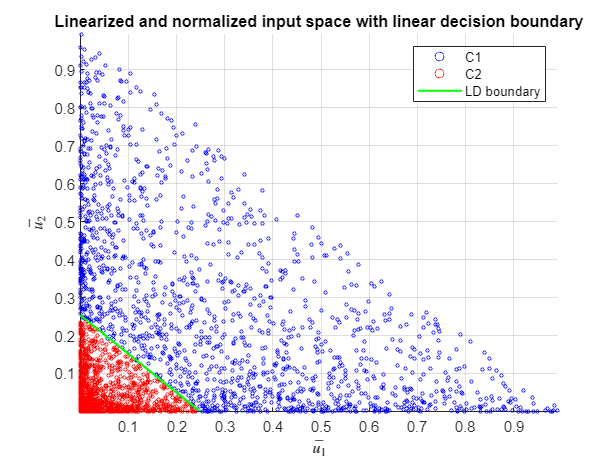

Utest_norm = normalize_data(Utest, Ntest);
Utest_linear =linearize_data(Utest_norm);

figure;
hold on;
grid on;
scatter(Utest_linear(Ytest(:) == 1,1),Utest_linear(Ytest(:) == 1,2),5,'b');
scatter(Utest_linear(Ytest(:) == 0,1),Utest_linear(Ytest(:) == 0,2),5,'r');
xlim([min(Utest_linear(:,1)), max(Utest_linear(:,1))]);
ylim([min(Utest_linear(:,2)), max(Utest_linear(:,2))]);
Xlim=xlim();
xspace = Xlim(1):0.1:Xlim(end);
LD_boundary = (theta(1) + xspace.*theta(2))./(-theta(3));
plot(xspace,LD_boundary,'g','LineWidth',1.5);
hold off;
title('Linearized and normalized input space with linear decision boundary');
xlabel('$\bar{u_1}$', 'Interpreter', 'latex');
ylabel('$\bar{u_2}$', 'Interpreter', 'latex');
legend({'C1','C2','LD boundary'});

And finally plot the non linearized input space of the test set with associated non linear decision boundary:

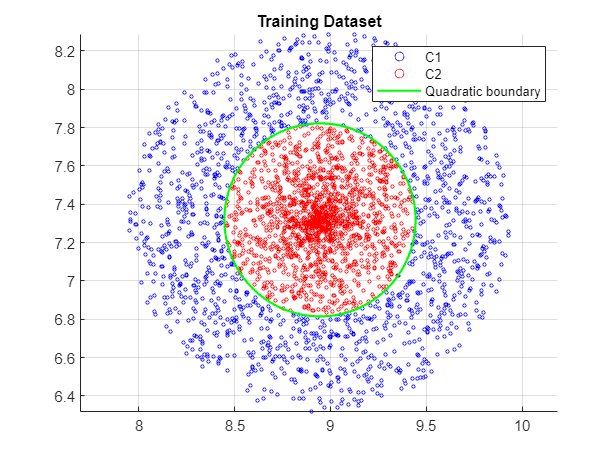

figure;
hold on 
grid on 
scatter(Utest_norm(Ytest(:) == 1,1),Utest_norm(Ytest(:) == 1,2),5,'b')
scatter(Utest_norm(Ytest(:) == 0,1),Utest_norm(Ytest(:) == 0,2),5,'r')
xlim([min(Utest_norm(:,1)), max(Utest_norm(:,1))]);
ylim([min(Utest_norm(:,2)), max(Utest_norm(:,2))]);
Quadratic_boundary = @(u1,u2) (theta(1)+theta(2)*(u1-mean(Utest_norm(:,1))).^2+theta(3)*(u2-mean(Utest_norm(:,2))).^2);
fimplicit(Quadratic_boundary, 'g', 'LineWidth', 1.5)
hold off
title('Training Dataset');
legend({'C1','C2','Quadratic boundary'});
axis equal;

And compute the error rate:

PHI_test = horzcat(ones(Ntest,1), Utest_linear);

e_newthon_test = error_rate(Ytest, PHI_test, theta, Ntest);
fprintf('Error rate: %f\t', e_newthon_test);

Error rate: 0.002333	